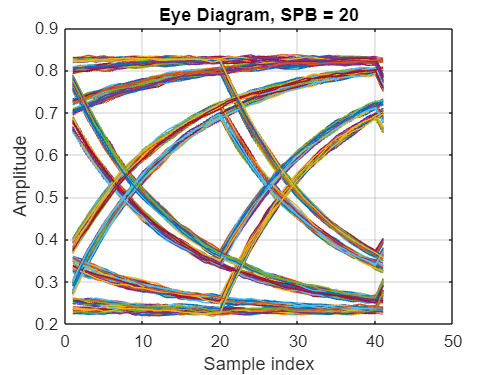

ch = Channel; % create communication channel
tx_bs=rand(1,1280)>0.5; % generate a random bit sequence
SPB=20; % bit time in samples

% transmit/receive bit sequence and compute BER
tx_wave = format_bitseq(tx_bs,SPB); % create waveform following protocol
    
% channel %
rx_wave = txrx(ch,tx_wave); % transmit waveform through channel
    
start_ind=find_start(rx_wave,ch); % find start bit

h=figure;   %  Do not change this code

% Place your code below that
%   1. Creates the eye diagram of rx_wave, plotting "2*SPB+1" samples in each trace.  
%      Hint: use for loop.
%   2. Superimposes all the traces on the same plot. 
%      Hint: use command hold on.  

for c = 1: 640
    n= 1: 2*SPB+1;
    block_ind = start_ind + c*2*SPB;
    plot(n,rx_wave(block_ind:block_ind+ 2* SPB));
    hold on;
end

% code to label plot -- do not modify
title('Eye Diagram, SPB = 20');
xlabel('Sample index')
ylabel('Amplitude');
grid on;